close all
clear all

## Step 1

%training inputs
X = (0:2)';
y = sin(X);

kernel = @(dist, sigmaf, L) sigmaf * exp(-(dist).^2/(2*L^2));
noise_var = 0.1;

% build Gram Matix K
Mdist = X - X'

Mdist =      0    -1    -2
     1     0    -1
     2     1     0


## Step 2.1: 

% build Kn
Kgram = kernel(Mdist, 1, 1) 

Kgram =     1.0000    0.6065    0.1353
    0.6065    1.0000    0.6065
    0.1353    0.6065    1.0000


Kn = Kgram + noise_var.*eye(length(X))

Kn =     1.1000    0.6065    0.1353
    0.6065    1.1000    0.6065
    0.1353    0.6065    1.1000


## Step 2.2: Cholesky factorization 

[L,p] = chol(Kn,'lower');
if p>0
    L = chol(Kn + 1e-9*eye(size(Kn)),'lower');  % numerical safety
end

## Step 2.3 

% part 1
% L*z = y: solve for z (intermediate vector)
z = L\y

z =          0
    0.9617
    0.3843



% part 2
% L' alpha = z: solve for alpha

alpha = L'\z

alpha =    -0.4878
    0.7831
    0.4548


## 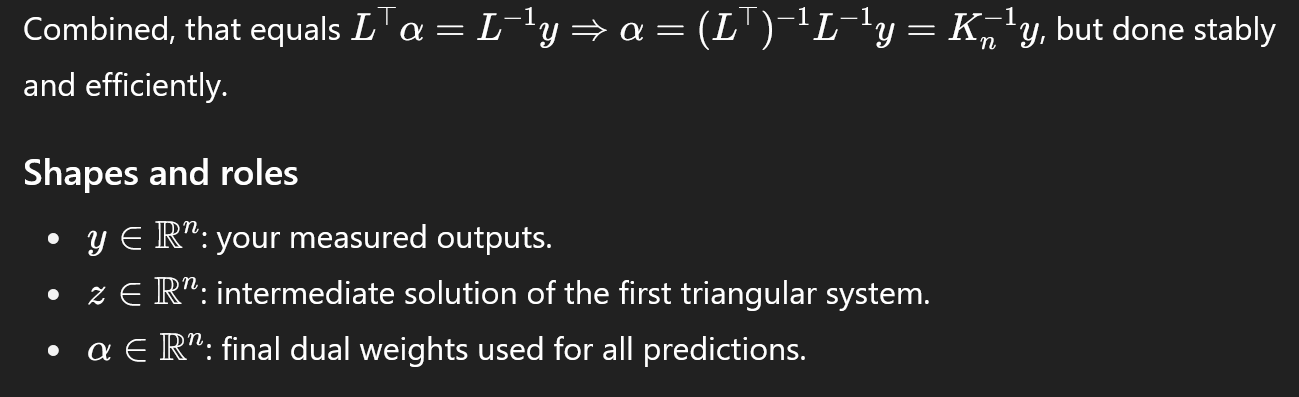

## Step 3

% cross covariance
x_star = 1.5; linspace(0, 3, 50);
k_star = kernel(X-x_star, 1, 1)

k_star =     0.3247
    0.8825
    0.8825


% predictive mean
mu_pred = k_star'*alpha

mu_pred = 0.9341

%predictive variance

## 

% solve Lw = k_star
w = L\k_star

w =     0.3095
    0.8040
    0.4187


w_mag = sum(w.^2)

w_mag = 0.9176

var_f_star = kernel(x_star - x_star, 1, 1) - w_mag

var_f_star = 0.0824

var_y_star = var_f_star + noise_var

var_y_star = 0.1824

std_y_star = sqrt(var_y_star);

% PLOTTING
ploty_var = [mu_pred + std_y_star', mu_pred - std_y_star']

ploty_var =     1.3612    0.5071


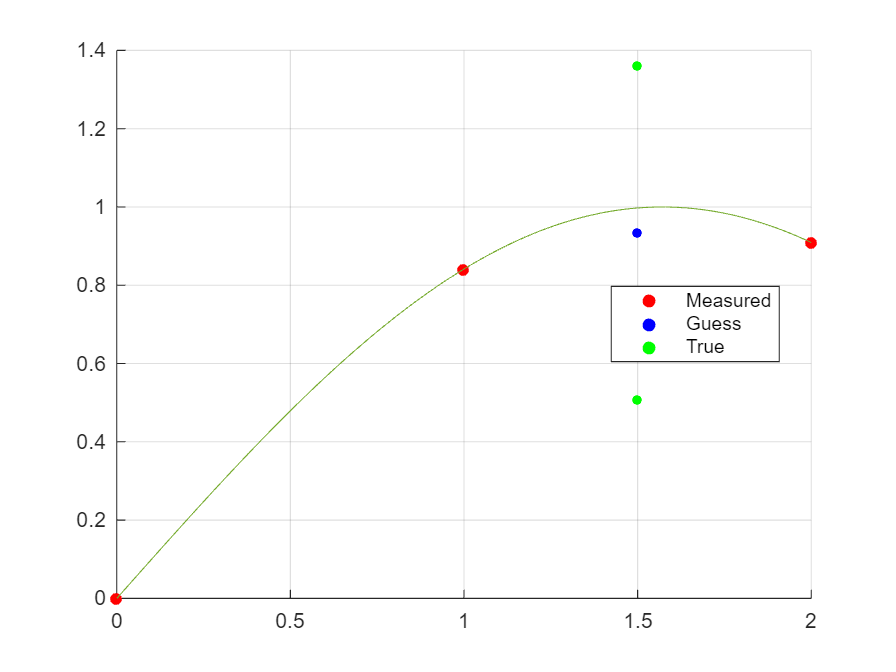

figure
hold on;
grid on;
scatter(X, y, 30, 'filled','r')
scatter(x_star,mu_pred, 20, 'filled', 'b')
scatter(x_star,ploty_var, 20, 'filled', 'g')
plotx = linspace(min(X), max(X), 101);
plot(plotx, sin(plotx))
legend("Measured", "Guess", "True", "Location","best");

## Step 4 

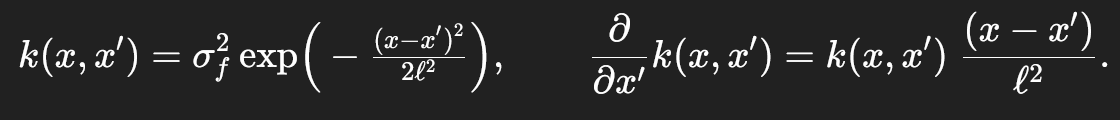

d_kernel_dxstar = @(dist, sigmaf, L) kernel(dist, sigmaf, L) .* (dist) / (L^2);
d_k_star  = d_kernel_dxstar(X - x_star, 1, 1)   % n×1

d_k_star =    -0.4870
   -0.4412
    0.4412


d_mu_pred = d_k_star' * alpha                   % scalar

d_mu_pred = 0.0927

## Step 5: 

% Key conditioning identity
x_new = 0.6;
k_new = kernel(X - x_new, 1, 1)

k_new =     0.8353
    0.9231
    0.3753


mu_new = k_new'*alpha

mu_new = 0.4862

w_new = L\k_new

w_new =     0.7964
    0.5287
   -0.0578


w_new_mag = sum(w_new.^2)

w_new_mag = 0.9171


var_f_new = kernel(x_new - x_new, 1, 1) - w_new_mag

var_f_new = 0.0829

var_y_new = var_f_new + noise_var

var_y_new = 0.1829

% posterior corss-covariance
% k(x_star, x_new) : scalar
k_xstar_xnew = kernel(x_star - x_new, 1, 1)

k_xstar_xnew = 0.6670


% k(x_star, X) : 1×n   → make it a column for the solve
k_xstar_X = kernel(x_star - X', 1, 1)'    % n×1

k_xstar_X =     0.3247
    0.8825
    0.8825



v_xstar = L \ k_xstar_X;                   % n×1
c_xstar = k_xstar_xnew - (v_xstar' * w_new);  % scalar

